## Preparando Datos

ds = datastore("../Datasets","ReadVariableNames",true,"VariableNamingRule","preserve");
data = generateData(ds);

compania = "AMZN";
datos = find(data.empresas == compania);
data(datos(1):datos(end),:);
campo1 = data.Date(datos(1):datos(end),:);
campo2 = data.Volume(datos(1):datos(end),:);
campo3 = data.Close(datos(1):datos(end),:)

campo3 = 1.0e+03 *

    0.0020
    0.0017
    0.0017
    0.0016
    0.0014
    0.0014
    0.0015
    0.0016
    0.0015
    0.0015


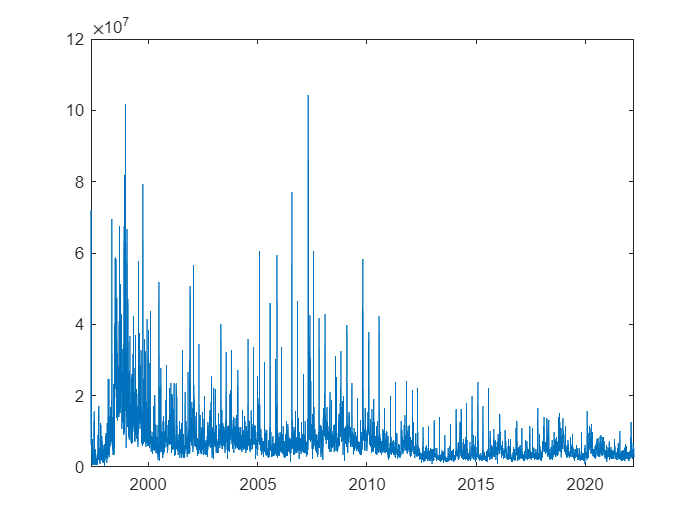

plot (campo1,campo2);

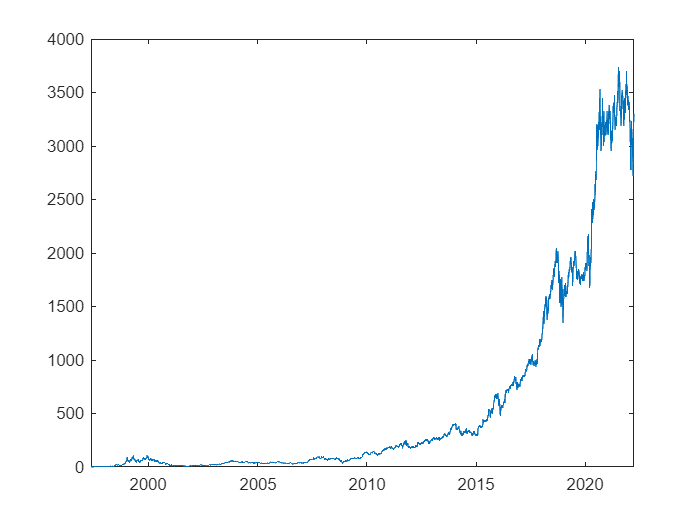

generateStatic(campo2);
plot(campo1,campo3);

generateStatic(campo3);


Funciones de Ayuda

function eti = generateLabels(label,size)
    eti = [];
    for i = 1:size
        eti = [eti ;label];
    end
    eti = table(eti);
end

function data = generateData(ds)
names = ds.Files;
[numFiles,~] = size(names);
files = [];
variables = [];
Tables = [];
for i = 1:numFiles
    nombre = string(names(i));
    table = readtable(nombre,"VariableNamingRule","preserve");
    variables = [variables table.Properties.VariableNames];
end
headers =  unique(variables);
[row,column] = size(headers);
uniqueHeaders = [];
for i = 1:column
    indices= find (variables== string(headers(i)));
    [~,occurrence] = size(indices);
    if occurrence == numFiles
        uniqueHeaders = [uniqueHeaders string(headers(i))];
    end
end
data = [];
for i = 1:numFiles
    tab = [];
    nombre = string(names(i));
    lastCSV = strfind(nombre,".csv");
    label = extractBetween(nombre,100,lastCSV-1);
    table = readtable(nombre,"VariableNamingRule","preserve");
    cabeceras = table.Properties.VariableNames;
    [~,num] = size(uniqueHeaders);
    for j = 1:num
        coin = find(cabeceras == uniqueHeaders(j));
        tab = [tab table(:,coin)];
    end
    [rows,~] = size(tab);
    tab = [tab generateLabels(label,rows)];
    data = [data;tab];
end
end

function statics = generateStatic(datos)
    statics = ["Media" "Mediana" "Moda" "Desviacion Estandar" "Varianza";mean(datos) median(datos) mode(datos) std(datos) var(datos)];
    statics = table(statics);

end